qrandstream usage

q = qrandstream('sobol',2,'Skip',100, 'Leap',1)

q = Sobol quasi-random stream in 2 dimensions

Point set properties:
              Skip : 100
              Leap : 1
    ScrambleMethod : none
        PointOrder : standard


q0 = qrand(q,100); % 反正态样本

q0 =     0.1484    0.7734
    0.3984    0.0234
    0.0859    0.5859
    0.3359    0.3359
    0.2109    0.2109
    0.4609    0.9609
    0.0547    0.9297
    0.3047    0.1797
    0.1797    0.3047
    0.4297    0.5547


q1 = norminv(q0);  % 正态样本

q1 =    -1.0432    0.7502
   -0.2574   -1.9874
   -1.3662    0.2171
   -0.4236   -0.4236
   -0.8032   -0.8032
   -0.0981    1.7617
   -1.6010    1.4735
   -0.5110   -0.9166
   -0.9166   -0.5110
   -0.1772    0.1375


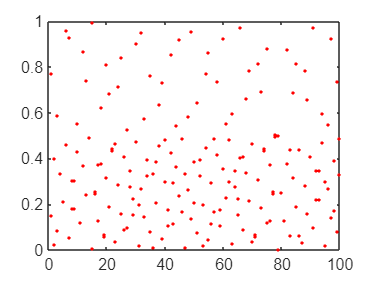

plot(q0,'r.');

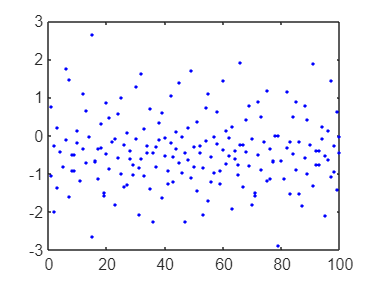

figure(2);
plot(q1,'b.'); 

Latin hypercube sample from normal distribution 

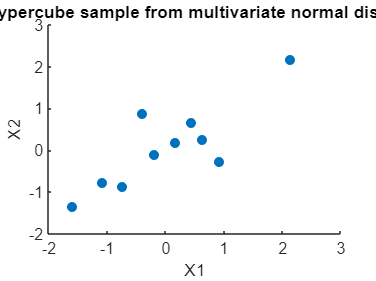

% Define the mean vector and covariance matrix of the multivariate normal distribution
mu = [0 0]; % zero mean
sigma = [1 0.5; 0.5 1]; % positive correlation

% Generate a Latin hypercube sample of size 10 from the multivariate normal distribution
X = lhsnorm(mu,sigma,10);

% Plot the sample points
scatter(X(:,1),X(:,2),'filled')
xlabel('X1')
ylabel('X2')
title('Latin hypercube sample from multivariate normal distribution');

ndgrid usage

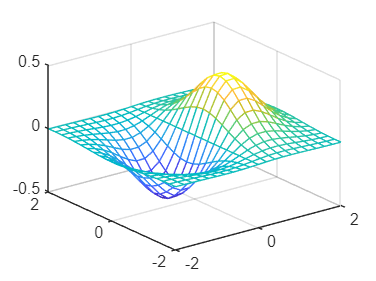

[X1,X2] = ndgrid(-2:.2:2);  % 输出参数个数给出了对应的维数, 后面分别给出对应的向量
Z = X1 .* exp(-X1.^2 - X2.^2);
mesh(X1,X2,Z)

K = cycle_Matrix(5);
K(4,:)

ans =      1     2     1     1     1


%%%%%%%%%%%%%%%%%% 多变量情况求解部分 %%%%%%%%%%%%%%%%%%%%% 

% ------------ 生成下标循环矩阵 ------------------- 

function grid_ = cycle_Matrix(n)
    [K{1:n}] = ndgrid(1:3);  % 为每一个对应的变量建立一个 3x3 矩阵 (其中, i_k  = 1,2,3); 
    grid_ = reshape(cat(n+1, K{:}), [], n); % 构造 9 * n 的矩阵, 每一格是grid经过reshape之后的值 
end